## Curve fitting con polyfit

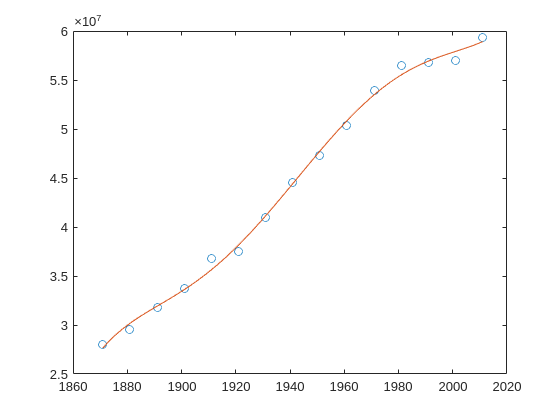

% https://seriestoriche.istat.it/
% Popolazione residente per sesso, nati vivi, morti, saldo naturale,
% saldo migratorio, saldo totale e tassi di natalità, mortalità, di
% crescita naturale e migratorio totale - Anni 1862-2014 ai confini attuali

anni = (1871:10:2011)';
popolazione = 1e6*[
    27.974
    29.552
    31.792
    33.739
    36.774
    37.491
    40.987
    44.562
    47.295
    50.374
    53.958
    56.479
    56.744
    56.961
    59.365
    ];

[p,~,mu] = polyfit(anni, popolazione, 5);
x = linspace(anni(1),anni(end));
pv = polyval(p, x, [], mu);

figure
plot(anni,popolazione,'o')
hold on
plot(x,pv)

## Regressione lineare con stima dell'errore con polyfit

x = 1:100; 
y = -0.3*x + 2*randn(1,100); 
[p,S] = polyfit(x,y,1)

p =    -0.2986   -0.2589


S = struct with fields:
           R: [2×2 double]
          df: 98
       normr: 19.2056
    rsquared: 0.9527


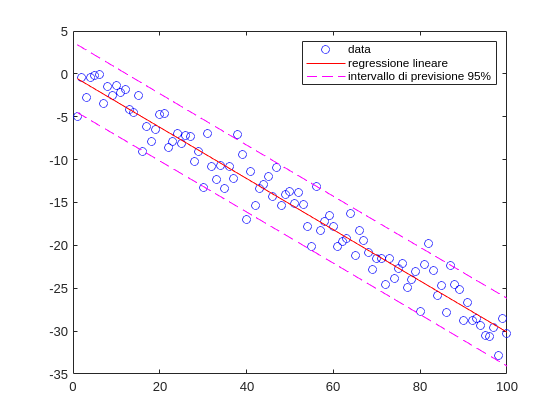

[f,delta] = polyval(p,x,S); % y+-delta 68%, y+-2delta 95%

figure
plot(x,y,'bo')
hold on
plot(x,f,'r-')
plot(x,f+2*delta,'m--',x,f-2*delta,'m--')
legend('data','regressione lineare','intervallo di previsione 95%') 

## Sistemi sottodeterminati e minimi quadrati

A = [1 2 0; 0 4 3];
b = [8; 18];
x = A\b % [0; 4; 2/3]

x =          0
    4.0000
    0.6667


## Fitting polinomiale

load census
whos cdate pop

  Name        Size            Bytes  Class     Attributes

  cdate      21x1               168  double              
  pop        21x1               168  double              



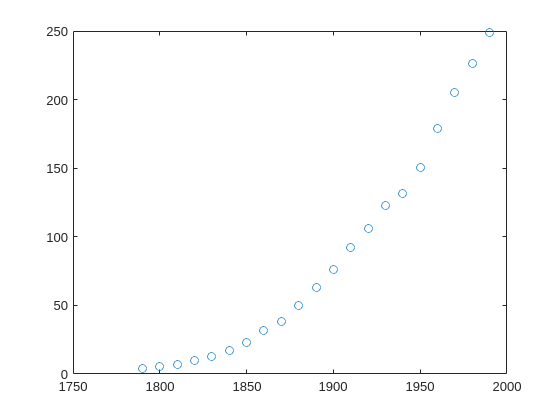

figure
plot(cdate,pop,'o')

### Fitting quadratico

[population2,gof] = fit(cdate,pop,'poly2');

fit requires one of the following:
  Curve Fitting Toolbox
  Model-Based Calibration Toolbox
  Predictive Maintenance Toolbox
  SimBiology
  Statistics and Machine Learning Toolbox

plot(population2,cdate,pop);
legend;


### Fitting polinomiale di grado 3, 4, 5, 6

population3 = fit(cdate,pop,'poly3','Normalize','on');
population4 = fit(cdate,pop,'poly4','Normalize','on');
population5 = fit(cdate,pop,'poly5','Normalize','on');
population6 = fit(cdate,pop,'poly6','Normalize','on');

hold on
plot(population3,'b');
plot(population4,'g');
plot(population5,'m');
plot(population6,'b--');
legend('cdate v pop','poly2','poly3','poly4','poly5','poly6');


### Fitting esponenziale con un termine (a*exp(b*x))

populationExp = fit(cdate,pop,'exp1');
plot(populationExp,'r--');
legend('cdate v pop','poly2','poly3','poly4','poly5','poly6','exp1');


### Residui

figure
plot(population2,cdate,pop,'residuals');
plot(populationExp,cdate,pop,'residuals');

% lista dei modelli
% https://it.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html

## Curve fitting interattivo con Curve Fitter

curveFitter
% usare anni, popolazione


## Curve fitting con modello personalizzato

x = [0.81;0.91;0.13;0.91;0.63;0.098;0.28;0.55;...
    0.96;0.96;0.16;0.97;0.96];
y = [0.17;0.12;0.16;0.0035;0.37;0.082;0.34;0.56;...
    0.15;-0.046;0.17;-0.091;-0.071];
ft = fittype('piecewiseLine( x, a, b, c, k )')

f = fit(x, y, ft, 'StartPoint', [1, 0, 1, 0.5]);
plot(f, x, y)